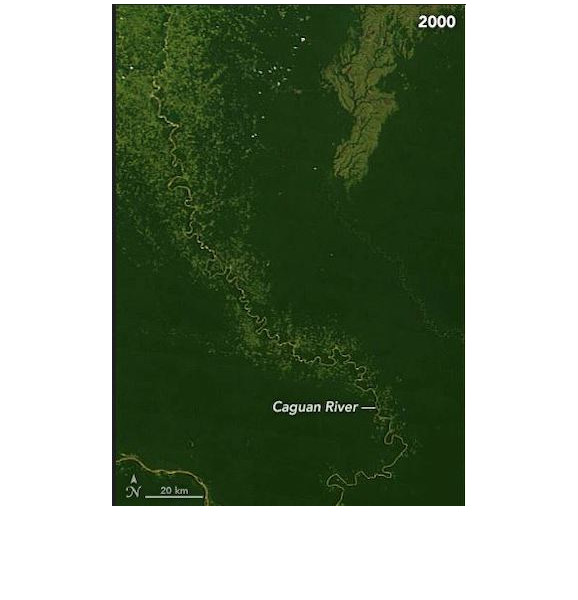

clear;
[M, N, ~] =size(imread("Image Series/imageSeries3_year2000.png"));
%M = 1701; N = 1913;
images = zeros(2, M, N, 3);
images(1,:,:,:) = imread("Image Series/imageSeries3_year2000.png");
images(2,:,:,:) = imread("Image Series/imageSeries3_year2017.png");
images = uint8(images);
imshow(squeeze(images(1,:,:,:)))

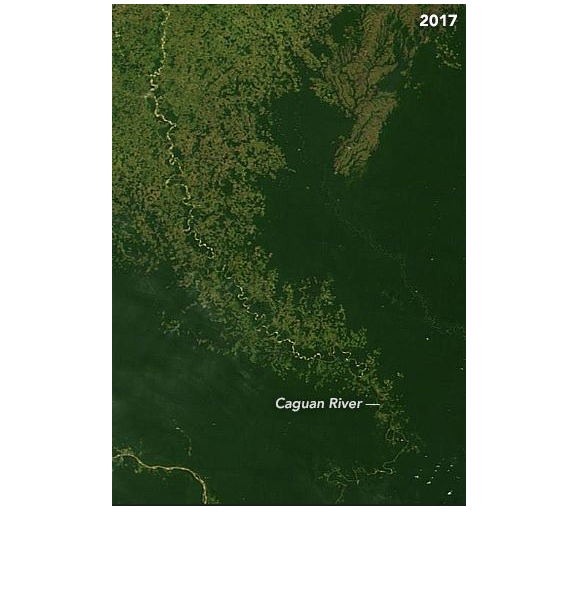

imshow(squeeze(images(2,:,:,:)))

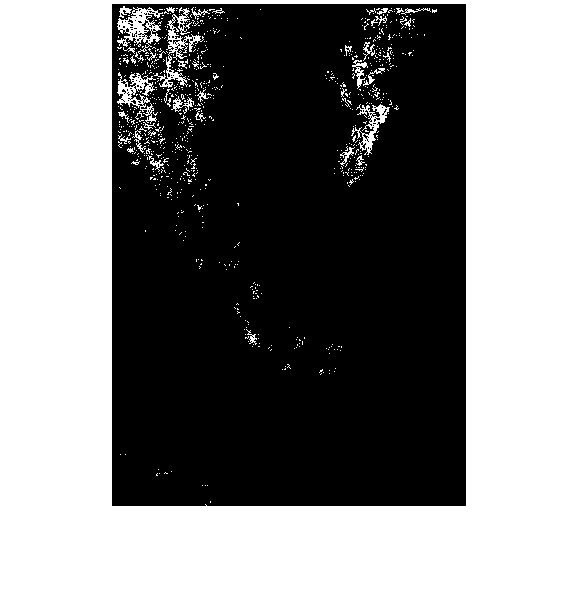



%remove text (figure out pixel values for text)
%thresholds specific to series of images (and goal)
%these thresholds for identifying river

hsvImage = rgb2hsv(squeeze(images(1,:,:,:)));

hueThresholdLow = 0;
hueThresholdHigh = graythresh(squeeze(hsvImage(:,:,1)));
saturationThresholdLow = graythresh(squeeze(hsvImage(:,:,2)));
saturationThresholdHigh = 1.0;
valueThresholdLow = graythresh(squeeze(hsvImage(:,:,3)));
valueThresholdHigh = 1.0;

hThresh = [hueThresholdLow  hueThresholdHigh];
sThresh = [saturationThresholdLow  saturationThresholdHigh];
vThresh = [valueThresholdLow  valueThresholdHigh];
thresholds = [hThresh; sThresh; vThresh];

[BW, idxs] = getMasks(images, thresholds);

imshow(squeeze(BW(1,:,:)))

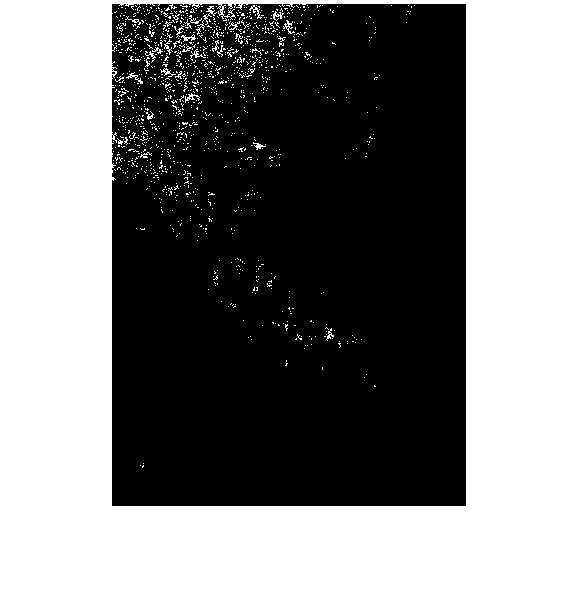

imshow(squeeze(BW(2, :,:)))



% %repeat mask then set prev mask's indices to 0
% 
% %these thresholds for identifying deforested areas
% 
% rThresh = [0 .21]; 
% gThresh=  [0 1];
% bThresh = [ 0 .791];
% thresholds = [rThresh; gThresh; bThresh];
% BW_removed = setZero(getMasks(images, thresholds), idxs);
% 
% imshow(squeeze(BW_removed(1,:,:)))
% imshow(squeeze(BW_removed(2,:,:)))
% 
% 
% 
% 
% %get percent of deforestation
% 
% deforestPercent = percentWhite(BW, idxs);
% 
% years = [2001, 2019];
% deforestArea = deforestPercent .*100; %assume 100 km area image for now
% bar(years, deforestArea);
% ylabel('KM^2')
% xlabel('Year')